M130 Lab 6

Start by checking the image properties of your assigned image and loading it into MATLAB

%Load your image, these are 2D images, make sure to use the new membrane images (1 point)
info = imfinfo('membrane_Image_2.tif')

info = struct with fields:
                     Filename: 'C:\Users\wangs\Downloads\membrane_Image_2.tif'
                  FileModDate: '25-May-2023 10:01:42'
                     FileSize: 1179967
                       Format: 'tif'
                FormatVersion: []
                        Width: 768
                       Height: 768
                     BitDepth: 16
                    ColorType: 'grayscale'
              FormatSignature: [77 77 0 42]
                    ByteOrder: 'big-endian'
               NewSubFileType: 0
                BitsPerSample: 16
                  Compression: 'Uncompressed'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: 319
              SamplesPerPixel: 1
                 RowsPerStrip: 768
              StripByteCounts: 1179648
                  XResolution: []
                  YResolution: []
               ResolutionUnit: 'Inch'
                     Colormap: []
          PlanarConfiguration: 'Chunky'
               

img = imread('membrane_Image_2.tif')

img = 768×768 uint16 matrix
   14637   14979   12339   12810   14525   15231   14773   15271   15585   13757   15785   15881   16287   17048   18191   17132   17082   18664   16984   18389   16543   17767   16707   17566   15101   15597   16181   14229   15292   15303   14931   14941   13571   12594   14406   13975   15662   15707   16423   18140   18637   17877   19141   18000   16378   16010   18008   15147   16433   18653
   13366   13382   12172   14211   13653   13317   14137   14265   14190   14610   16046   15219   16396   15771   16921   16271   16954   15988   17421   16014   15038   17296   15455   13279   16162   15505   14939   15372   16672   14356   13915   15260   14140   12835   12900   14361   14876   14149   16901   16900   16762   17899   17337   17600   17605   16772   16224   16200   16555   13613
   12195   11826   12875   13125   15018   12600   12702   15412   13327   14861   14520   15442   14740   16171   16520   15406   15806   16172   16166   17563   14961  

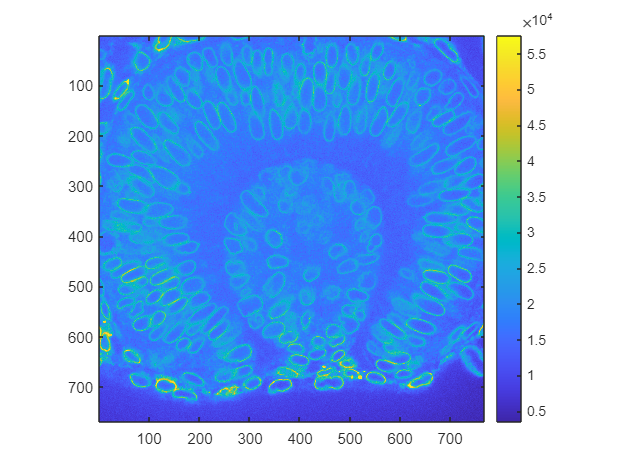

imagesc(img)
colorbar
axis image

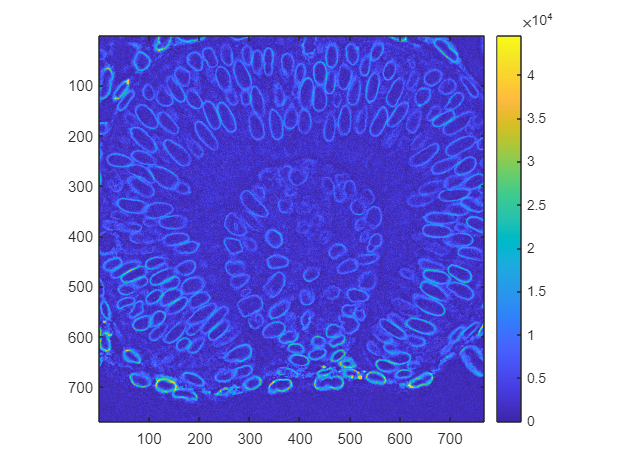

%Image processing tasks (4 points):
%Perform background subtraction by morphological opening. Pick a large
%radius for the strel function that would extend outside of any objects
%in the foreground    
bg = imopen(img,strel('disk',10)); 
img_bg = img-bg; % perform background subtraction
imagesc(img_bg)
colorbar 
axis image

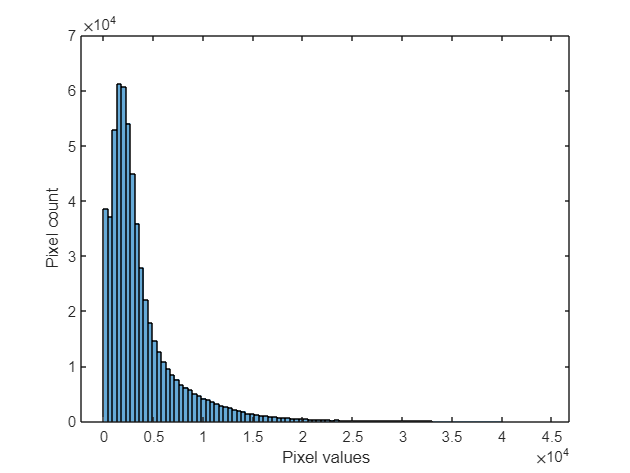


%Perform Intensity Thresholding
%Test manual, Otsu's and adaptive thresholding approaches and pick the one
%you like best to use for the rest of the lab

% picking a threshold by examining pixel value 
histogram(double(img_bg(:)), 100)
xlabel('Pixel values')
ylabel('Pixel count')

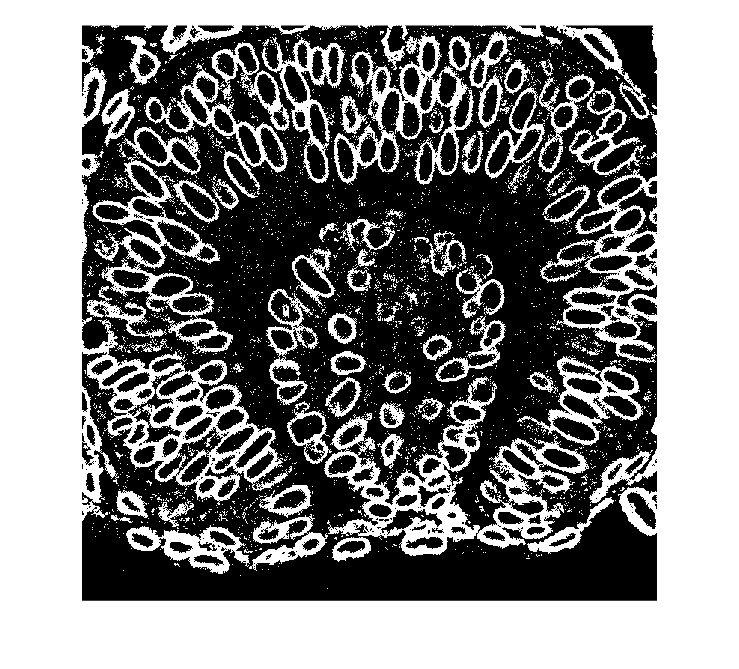

thresh = 4500; %this is the threshold because majority of the pixels are less than 4500
bw = img_bg >thresh; 
imshow(bw)

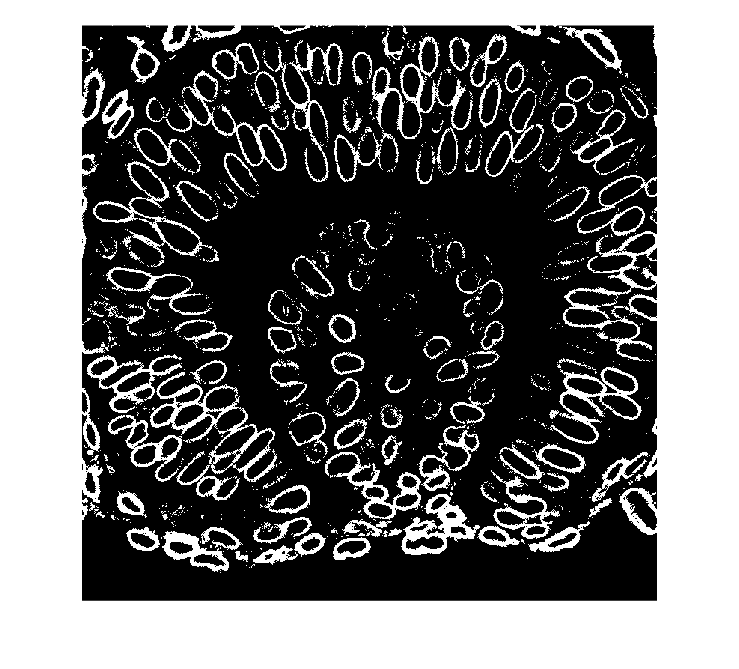

otsu = imbinarize(uint16(img_bg),"global");
imshow(otsu)

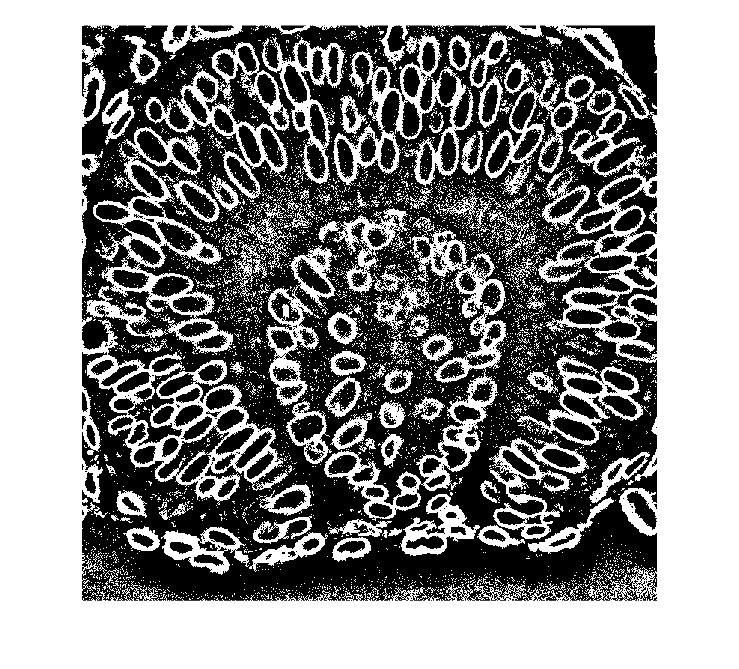

adaptive = imbinarize(uint16(img_bg), "adaptive"); 
imshow(adaptive)

imshow(otsu)

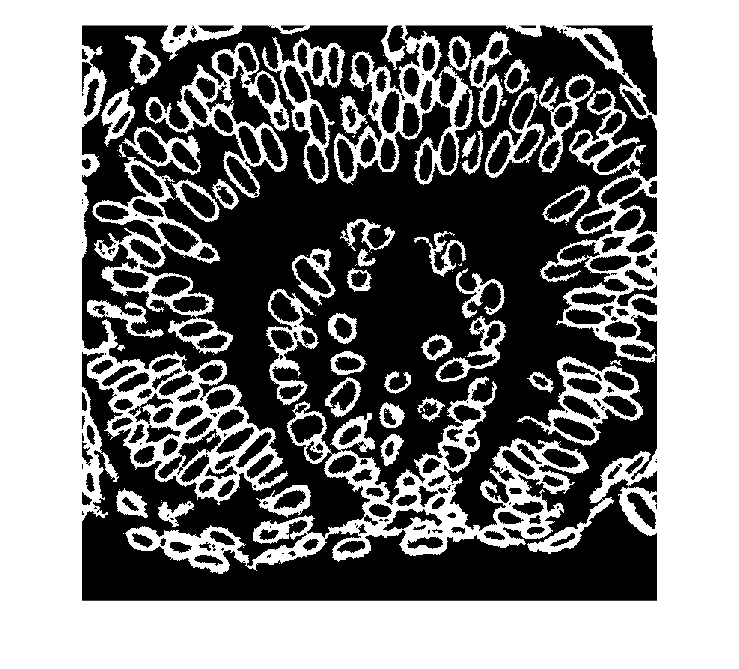

bw = bwareaopen(bw,200);
bw = imclose(bw,strel('disk',1));
imshow(bw)

%Manual thresholding method seems to perform better, we will use it
%for the rest of the lab 

%Given the image, decide whether you want to attempt the watershed using
%the distance transform or the Laplacian.
%If using the distance transform, denoise using a Gaussian blur
%If using the LoG, calculate the Laplacian kernel, guess and check to find
%a value for c that gives you a clear minimum near the middle of each
%object

disp('Given the image, I want to attempt the watershed method using the Laplacian')

Given the image, I want to attempt the watershed method using the Laplacian


disp(['The image has more similar, uniform cell sizes, not too many cells have extraneously ' ...
    'smaller radius or larger radius'])

The image has more similar, uniform cell sizes, not too many cells have extraneously smaller radius or larger radius


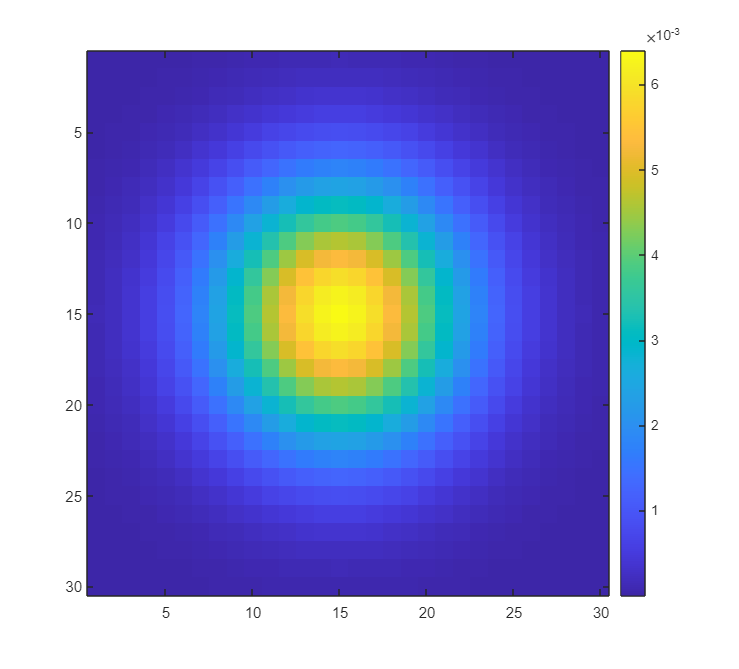

%Generate a Gaussian
gaussian = zeros(30);
m = 30;
n = 30;
c = 5; % A c value of 5 will give a clear minimum near the middle of each object 
for x = 1:n
    for y = 1:m
        gaussian(y,x) = exp(-1*((x-n/2)^2+(y-m/2)^2)/(2*c^2));
    end
end
gaussian = gaussian./sum(gaussian(:));
imagesc(gaussian)
colorbar

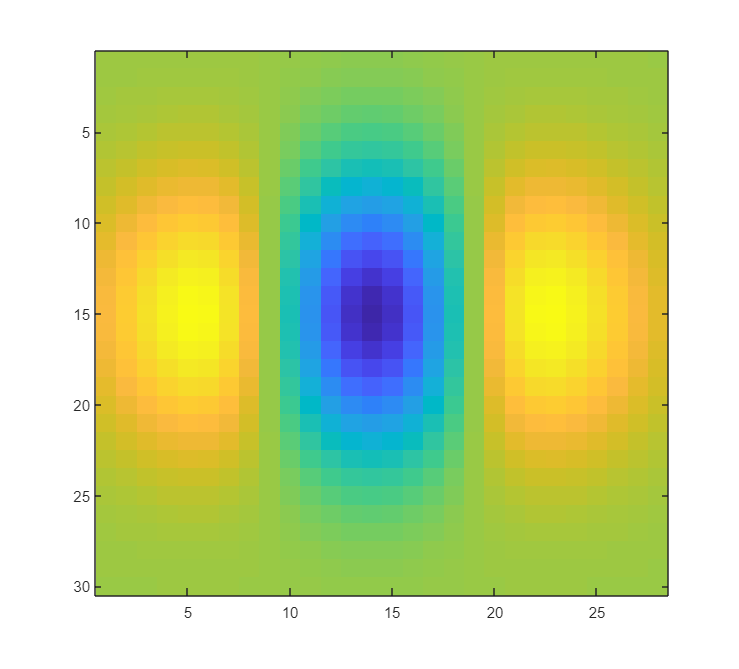


%Laplacian of Gaussian as a kernel in 2D view. 
% Take the derivative of gaussian, twice, in the second dimension 
ddx = diff(gaussian,2,2); 
%take the derivative of gaussian, twice, in the second dimension 
ddy = diff(gaussian,2,1);
imagesc(ddx)

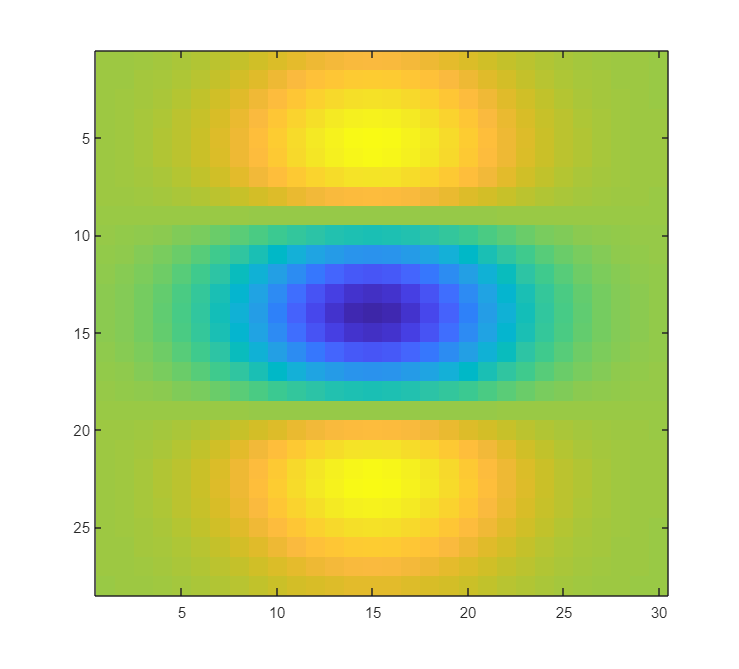

imagesc(ddy) 

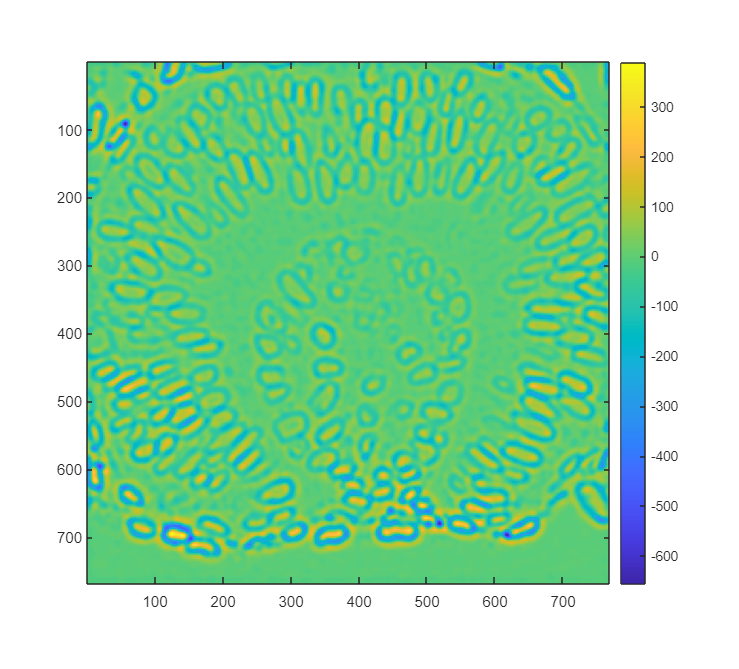

img_log = conv2(img_bg,ddx,'same') + conv2(img_bg,ddy,'same'); %convolution of img_bg and the laplacian
imagesc(img_log)
colorbar
axis image

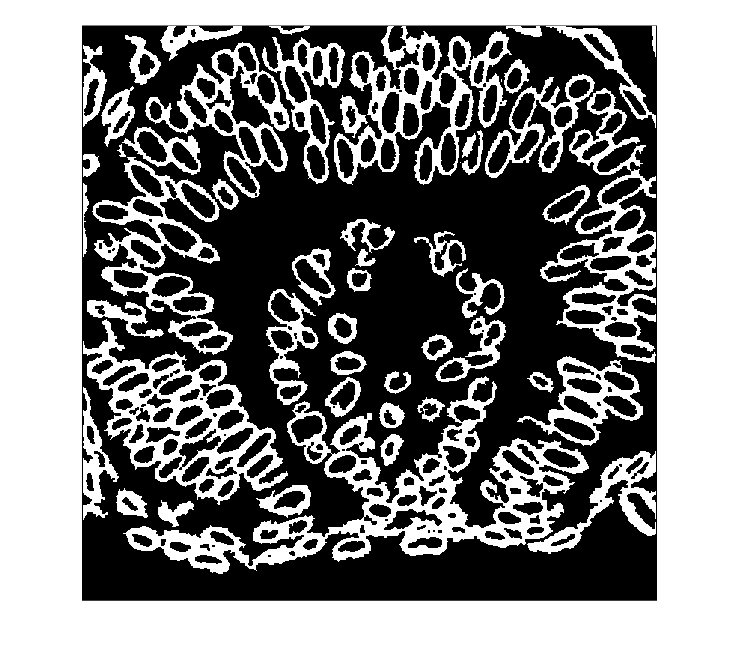

%Clean up the segmentation by mathematical morphology
%Threshold and apply basic cleanup, this took a little trial and error since
%the example is so dim and noisy
bw = imbinarize(uint16(bw),'global');
bw = bwareaopen(bw,30); %notes: clean up 
bw = bwmorph(bw,'close',1);
bw = bwareaopen(bw,5);
imshow(bw)

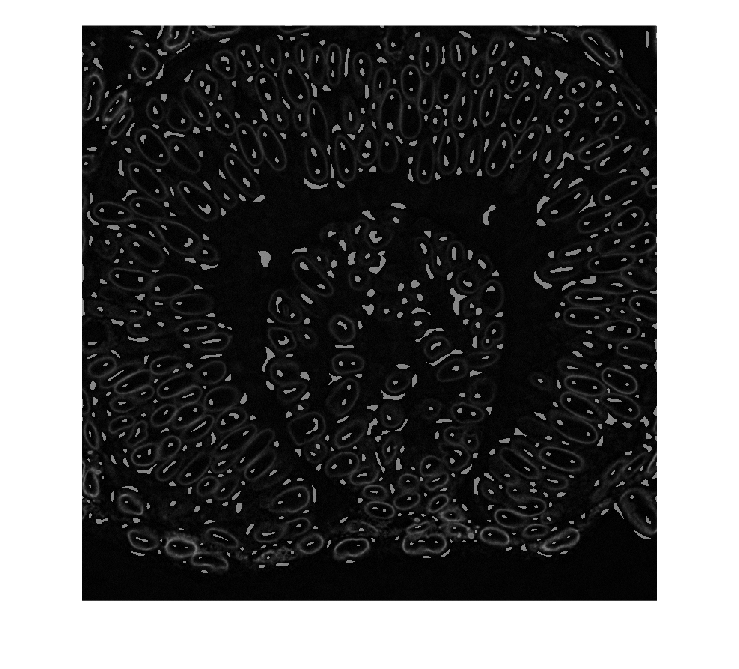

%Further refine the segmentation using the watershed transform (3 points)
%imextendedmin finds all touching pixels that are a local minimum
%take the complement of img_log so that the centers are minima
%note: Further refine the segmentation 
log_minima = imcomplement(img_log);
mask = imextendedmin(log_minima,20); %calculation of local minimum, localized points can be tested on different values. 
imshowpair(img_bg,mask,'blend') %more lower values, more localized mins 

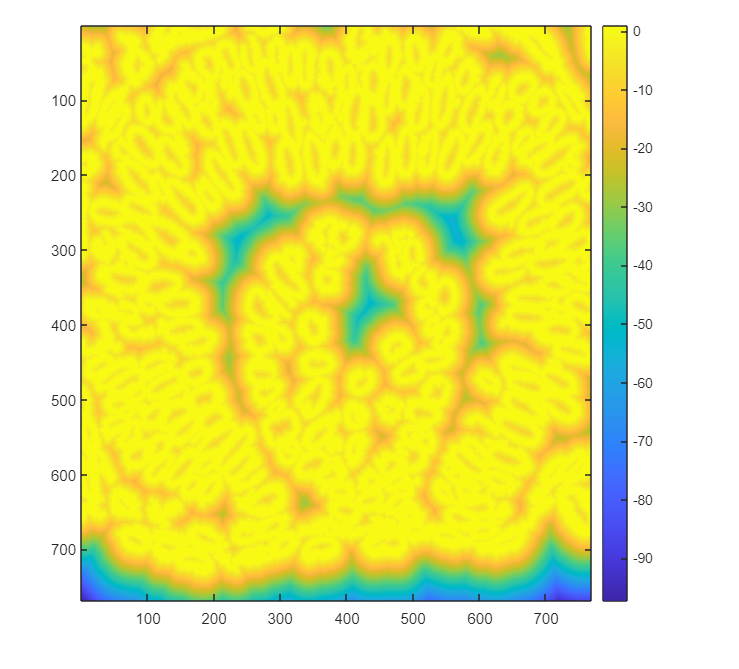

D = imcomplement(bwdist(bw));
imagesc(D)
colorbar

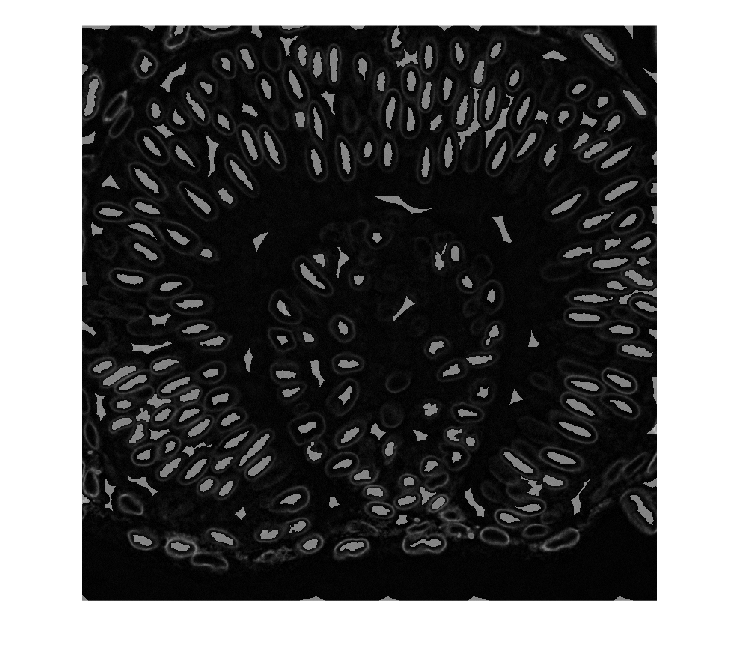

%imextendedmin finds all touching pixels that are a local minimum
%take the complement of img_log so that the centers are minima
mask = imextendedmin(D,5);
imshowpair(img_bg, mask,'blend')

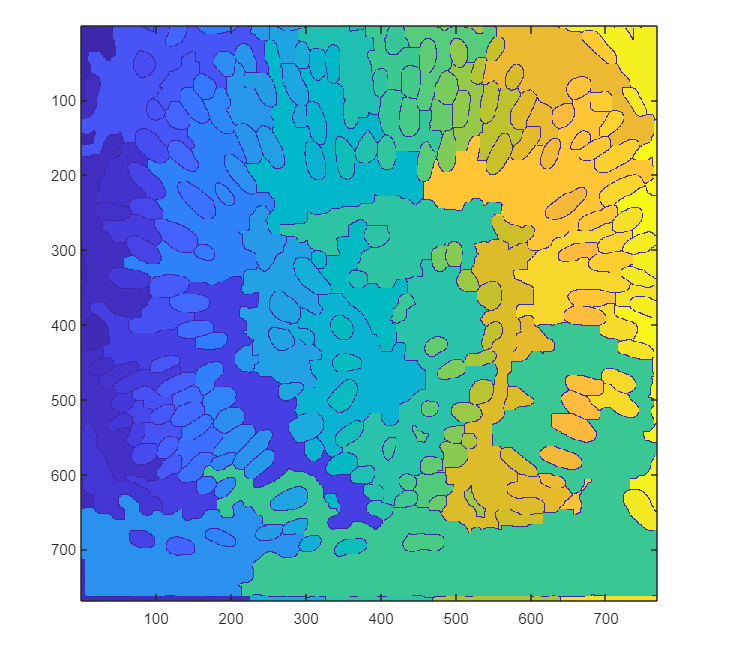


%imimposemin takes the local minima we found above and forces those to be
%the only minima in the original distance transform, ensuring that each
%will be the center of a region found by the watershed transform
img_log_minima = imimposemin(log_minima,mask); %note: further refine. 
Ld2 = watershed(img_log_minima); %perform watershed
imagesc(Ld2)

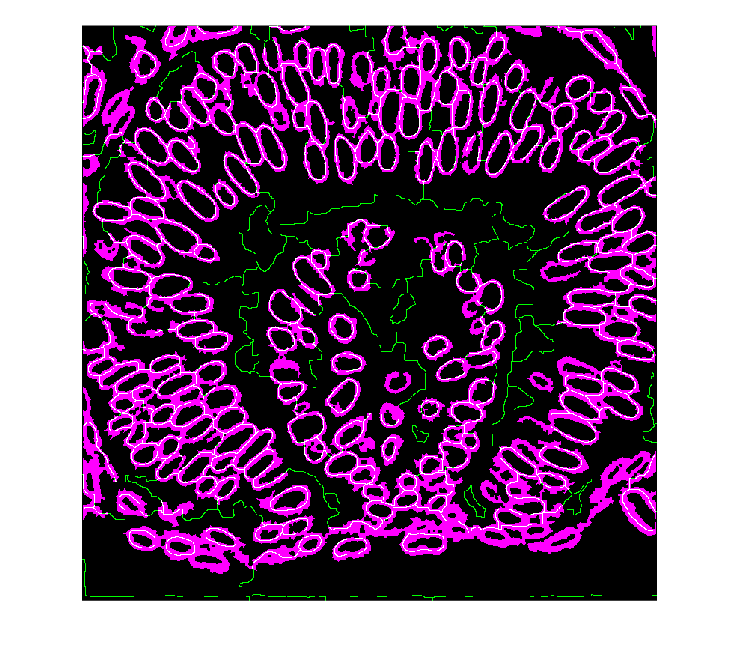

%We now find all pixels in the watershed transform that are = 0, these are
%the cell boundaries computed based on the watershed. The foreground
%objects in Ld2 correspond to the interior area of each cell!
bw2 = Ld2==0;
imshowpair(bw2,bw)

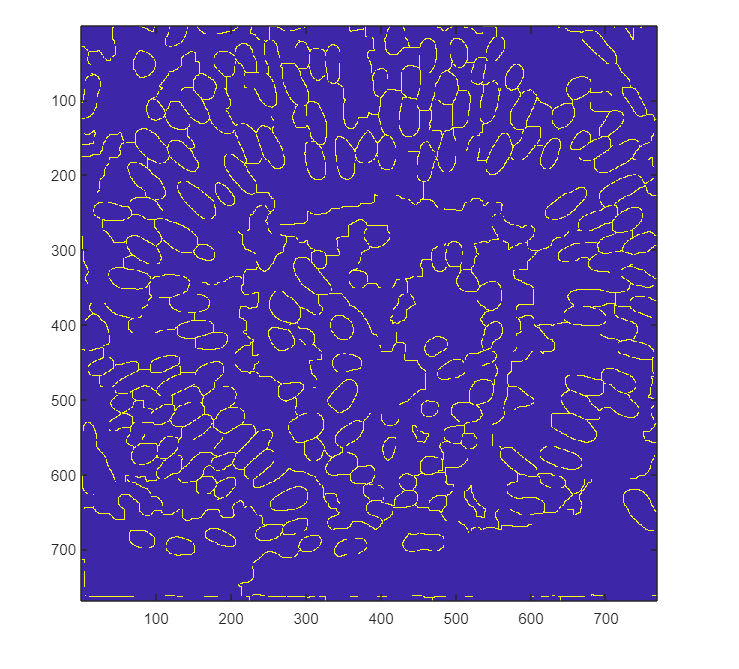

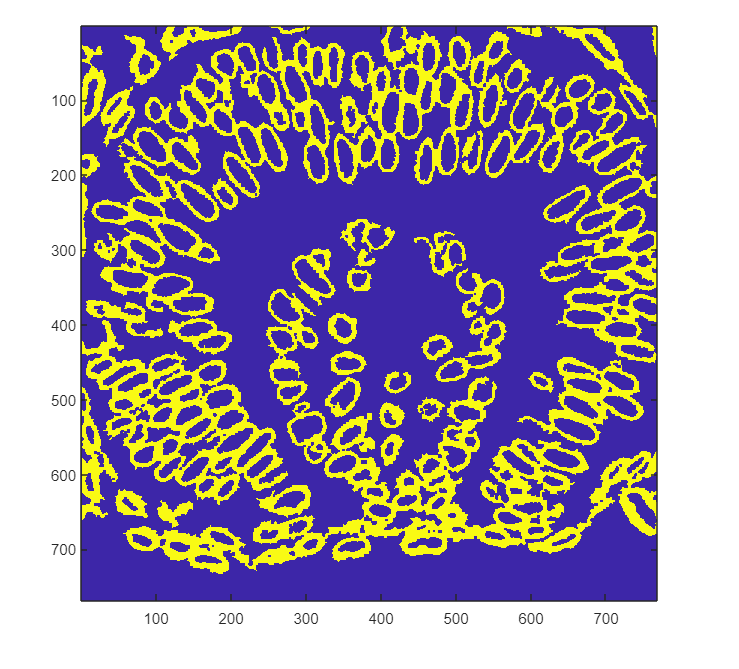

imagesc(bw2)

The cells are clearly demarcated with cell boundaries now. 

%Discuss the results, did the watershed improve segmentation quality at
%all? (1 point)

Watershed improved the image segmentation quality immensely because a watershed is created at each identified local minima, so after we have reduced noise, we can successfully trace the border at high accuracy. 

Share some feedback, what's working for you? what's not working for you? what concepts are you struggling with the most? (1 point)

I tried the LoG method at watershed this time: so far everything has been working, I am most struggling with the imcomplement function, which I will need to look up the documentation for. 